# Depth and Semantic Segmentation Visualization Using Unreal Engine Simulation

This example shows how to visualize depth and semantic segmentation data captured from a camera sensor in a simulation environment. This environment is rendered using the Unreal Engine® from Epic Games®.

You can use depth visualizations to validate depth estimation algorithms for your sensors. You can use semantic segmentation visualizations to analyze the classification scheme used for generating synthetic semantic segmentation data from the Unreal Engine environment.

## Model Setup

The model used in this example simulates a vehicle driving in a city scene.

- A [Simulation 3D Scene Configuration](docid:uav_ref#mw_96a521fd-316f-497b-bc01-b2c5f4083563) block sets up simulation with the [US City Block](docid:uav_ref#mw_c39cc898-f165-40e0-b5bc-635e3b275057) scene.

- A [Simulation 3D UAV Vehicle](docid:uav_ref#mw_619937da-a01b-431e-88b5-4f39caf0b95a) block specifies the driving route of the vehicle.

- A [Simulation 3D Camera](docid:uav_ref#mw_e9491451-3198-4988-8ef1-6a3878d29155) block mounted to the quadrotor captures data from the flight. This block outputs the camera, depth, and semantic segmentation displays by using [To Video Display](docid:vision_ref#f14522) (Computer Vision Toolbox) blocks.

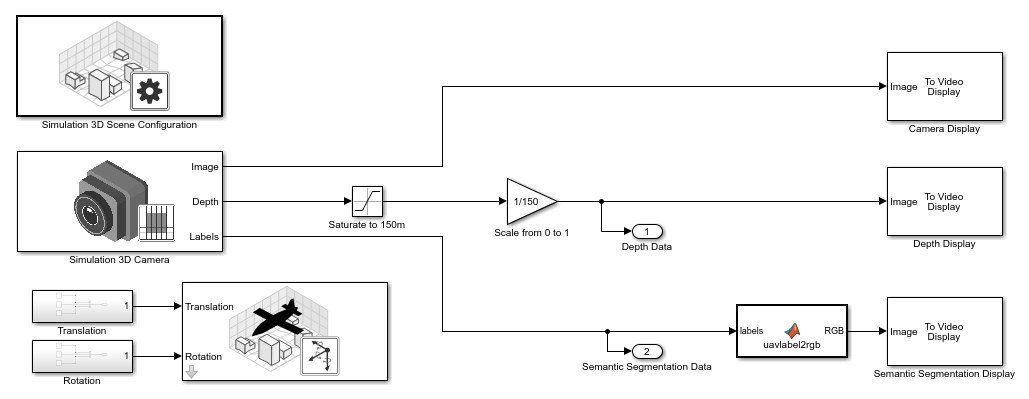

## Depth Visualization

A depth map is a grayscale representation of camera sensor output. These maps visualize camera images in grayscale, with brighter pixels indicating objects that are farther away from the sensor. You can use depth maps to validate depth estimation algorithms for your sensors.

The **Depth** port of the Simulation 3D Camera block outputs a depth map of values in the range of 0 to 1000 meters. In this model, for better visibility, a Saturation block saturates the depth output to a maximum of 150 meters. Then, a Gain block scales the depth map to the range [0, 1] so that the To Video Display block can visualize the depth map in grayscale.

## Semantic Segmentation Visualization

*Semantic segmentation* describes the process of associating each pixel of an image with a class label, such as *road*, *building*, or *traffic sign*. In the 3D simulation environment, you generate synthetic semantic segmentation data according to a label classification scheme. You can then use these labels to train a neural network for UAV flight applications, such as landing zone identification. By visualizing the semantic segmentation data, you can verify your classification scheme.

The **Labels** port of the Simulation 3D Camera block outputs a set of labels for each pixel in the output camera image. Each label corresponds to an object class. For example, in the default classification scheme used by the block, `1` corresponds to buildings. A label of `0` refers to objects of an unknown class and appears as black. For a complete list of label IDs and their corresponding object descriptions, see the **Labels** port description on the [Simulation 3D Camera](docid:uav_ref#mw_e9491451-3198-4988-8ef1-6a3878d29155) block reference page.

The MATLAB® Function block uses the [`label2rgb`](docid:images_ref#f6-333611) function to convert the labels to a matrix of RGB triplets for visualization. The colormap is based on the colors used in the CamVid dataset, as shown in the [Semantic Segmentation Using Deep Learning](docid:vision_ug#mw_c671533a-9d94-4d6a-bef0-2982e5d45318) example. The colors are mapped to the predefined label IDs used in the default Unreal Engine simulation scenes. The helper function `sim3dColormap` defines the colormap. Inspect these colormap values.

open sim3dColormap.m

## **Model Simulation**

Run the model.

sim('uav_ue4_depth_imaging.slx');

When the simulation begins, it can take a few seconds for the visualization engine to initialize, especially when you are running it for the first time. The `MathWorks_Aerospace` window displays the scene from the scene origin. In this scene, the quadrotor UAV flies a short distance down one city block.

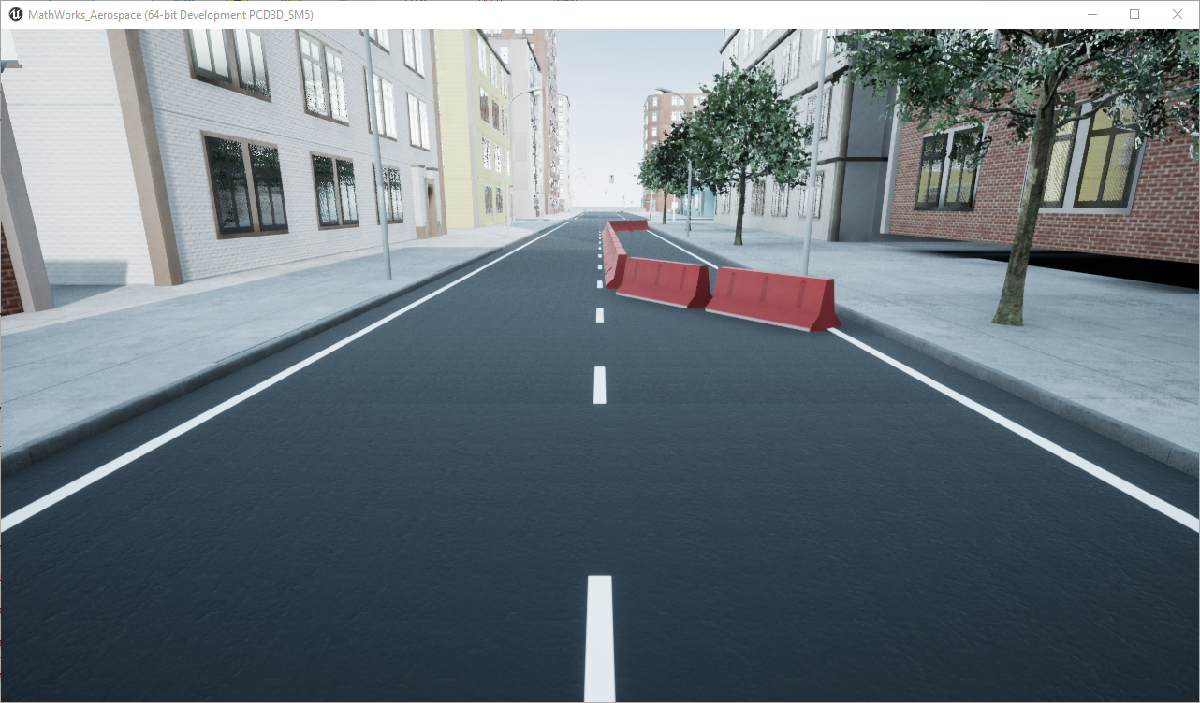

The Camera Display, Depth Display, and Semantic Segmentation Display blocks display the outputs from the camera sensor.

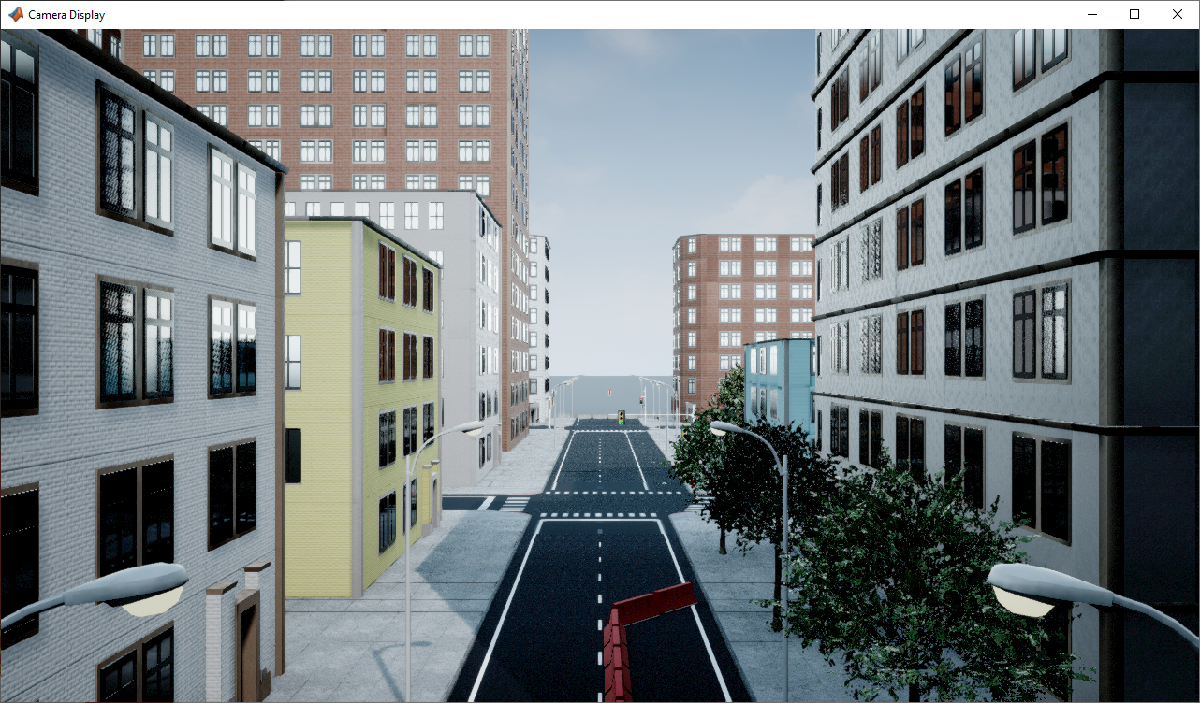

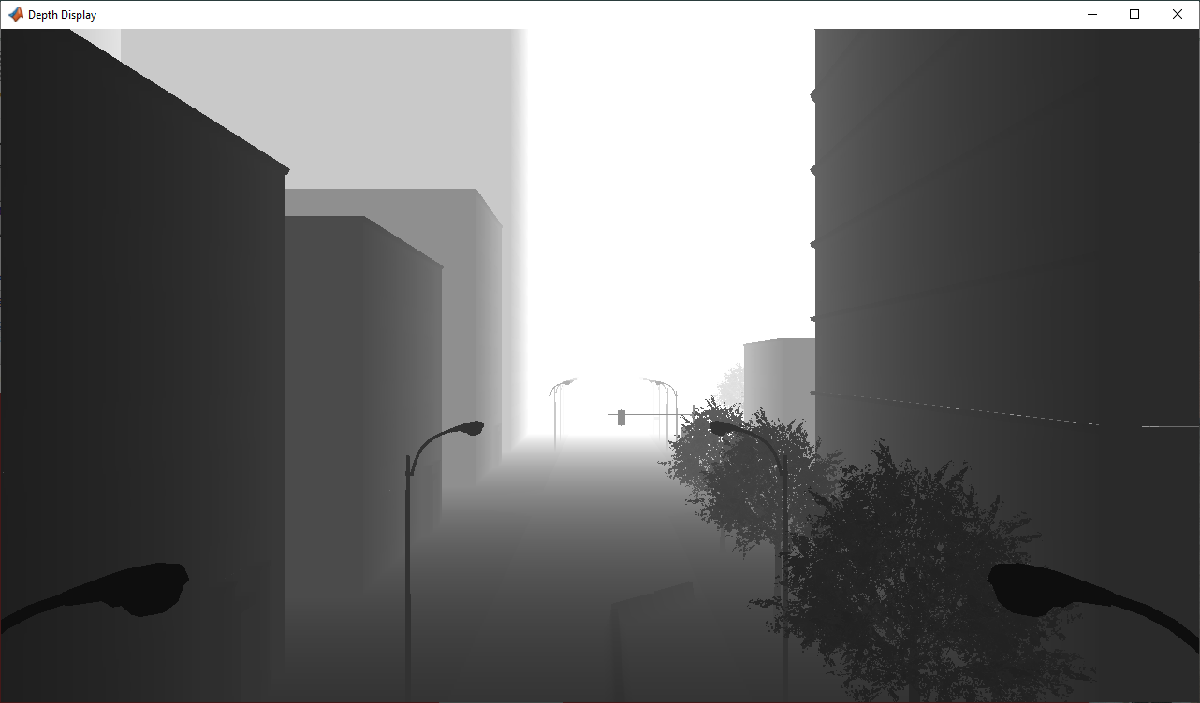

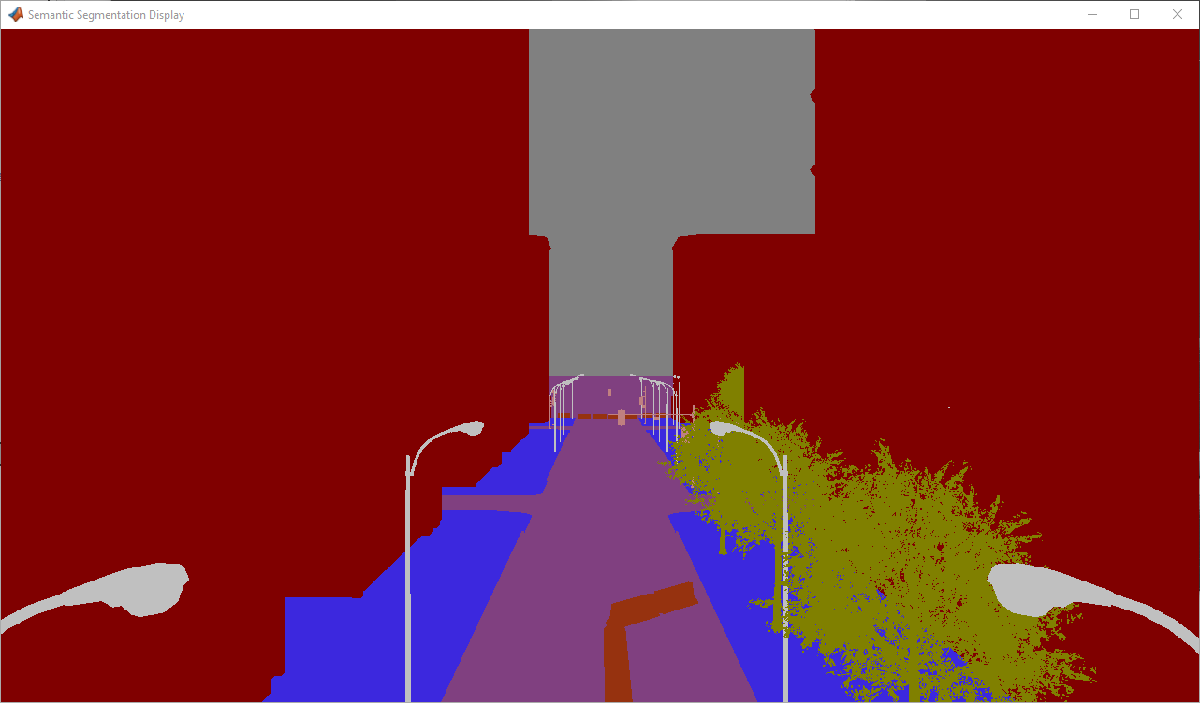

To change the visualization range of the output depth data, try updating the values in the Saturation and Gain blocks.

To change the semantic segmentation colors, try modifying the color values defined in the `sim3dColormap` function. Alternatively, in the uav`label2rgb` MATLAB Function block, try replacing the input colormap with your own colormap or a predefined colormap. See [`colormap`](docid:matlab_ref#buc3wsn-1).

*Copyright 2020 The MathWorks, Inc.*